                                 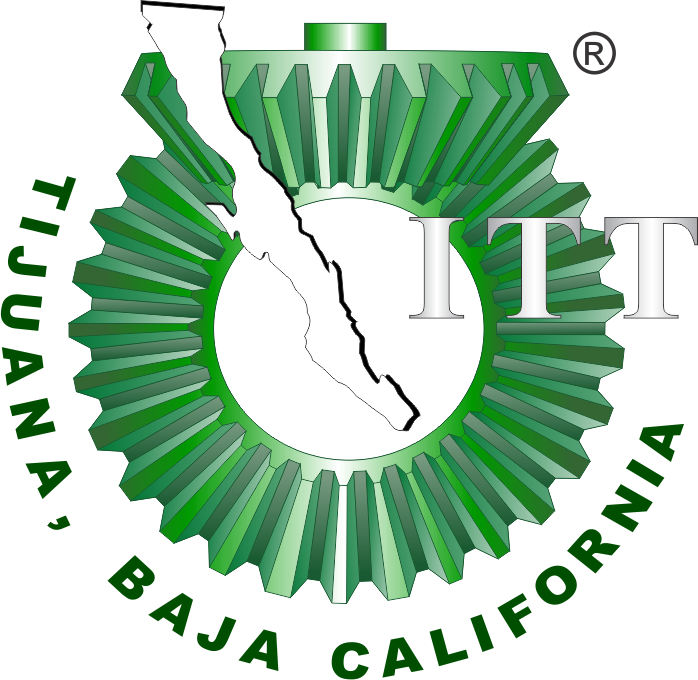

# Proyecto final: Actividad electrica del utero

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

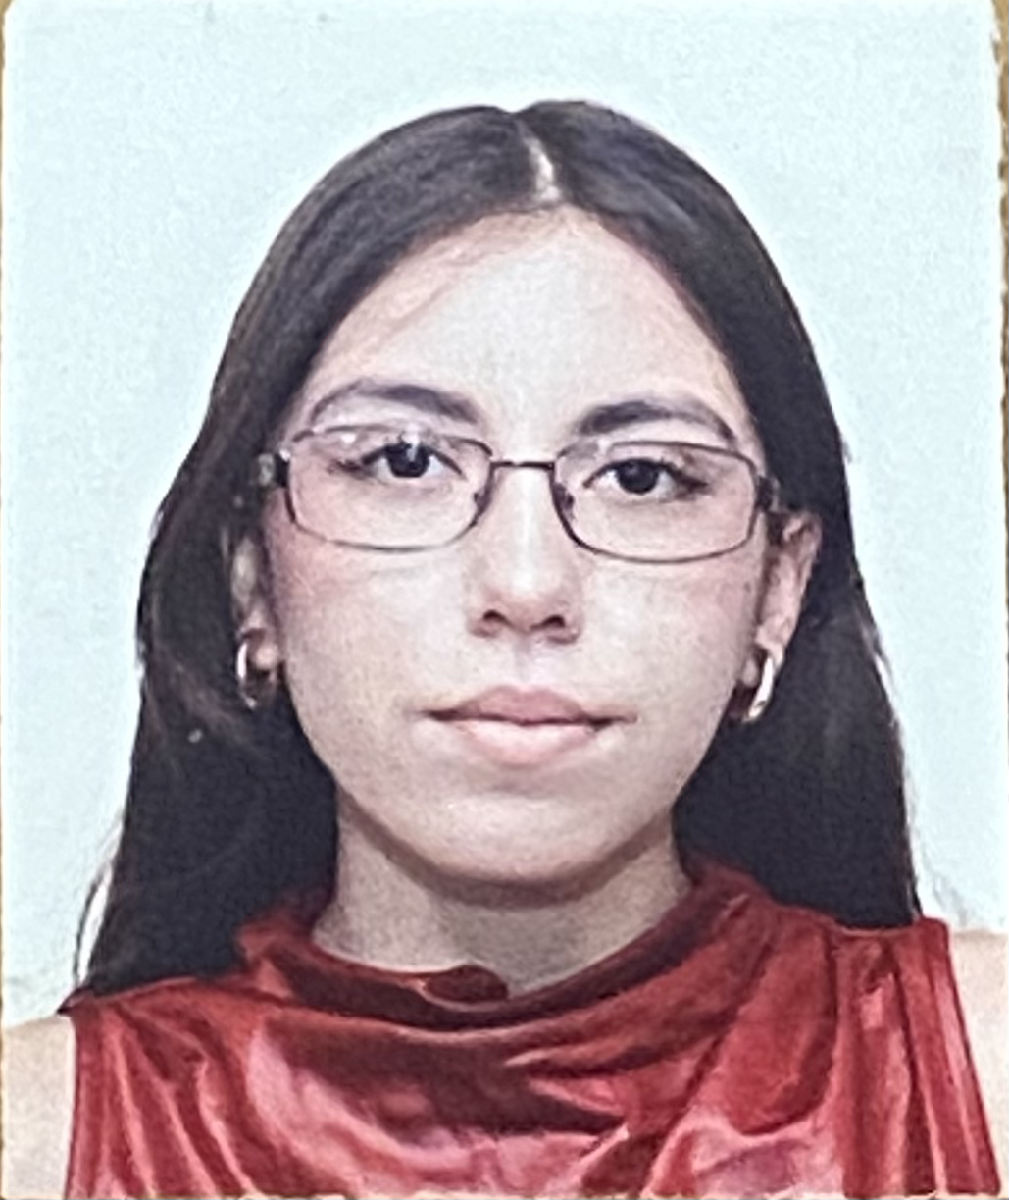

Nombre del alumno: Lopez Pardo Brianna Vanessa

Número de control: 22212261

Correo institucional: L22212261**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación 

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema';
open_system(file);
parameters.StopTime= tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Lazo cerrado

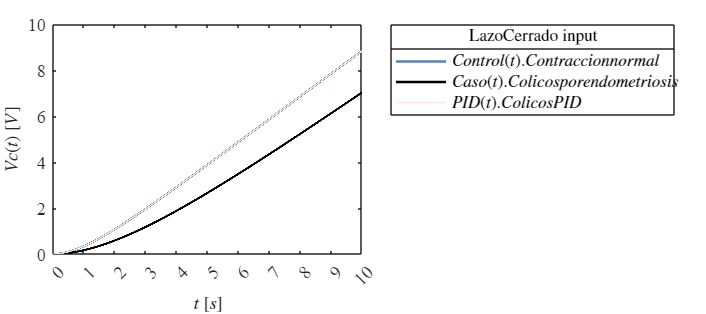

x = sim(file, parameters);
plotsignals(x.t,x.control,x.caso, x.pid)

## Lazo abierto

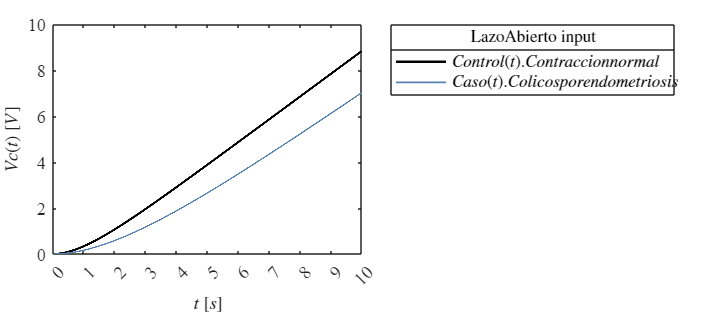

x = sim(file, parameters);
plotSignals(x.t,x.control,x.caso)

## Funcion: Respuesta en lazo cerrado

function plotsignals(t,control,caso, pid)

Signal = 'LazoCerrado';


set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman', 'FontSize', 11)
hold on; grid off; box on;

mycolors = [86,130,177;
    0,0,0;
    255,232,219;
    255,232,219;
    10,51,160;
    30,80,90]/255;
colororder(mycolors)
    
   p=   plot(t,control,'-',t,caso,'-',t,pid, ...
        'LineWidth',1.5,'MarkerSize',3,'MarkerIndices',1:1000:length(t));
    set(p(3),'LineWidth',1);
    L = legend('$Control(t). Contraccion normal$','$Caso(t). Colicos por endometriosis$','$PID(t). Colicos PID$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
     title(L,[Signal,' input'],'FontSize',10)

    xlabel('$t$ $[s]$', 'Interpreter', 'latex','FontSize', 11)
    ylabel('$Vc(t)$ $[V]$', 'Interpreter', 'latex','FontSize', 11)

    xlim([0,10]);xticks(0:1:10);

 
     exportgraphics(gcf,[Signal,'.pdf'],'ContentType', 'vector');
     exportgraphics(gcf,[Signal,'.png'],'ContentType', 'vector');
end



## Funcion: Respuesta en lazo abierto

function plotSignals(t,control,caso)

Signal = 'LazoAbierto';

set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman', 'FontSize', 11)
hold on; grid off; box on;

mycolors = [0,0,0;
    86,130,177;
    115,158,201;
    255,232,219;
    10,51,160;
    30,80,90]/255;
colororder(mycolors)
    
   p=   plot(t,control,'-',t,caso,'-', ...
        'LineWidth',1.5,'MarkerSize',2,'MarkerIndices',1:1000:length(t));
    set(p(2),'LineWidth',1);
    L = legend('$Control(t). Contraccion normal$','$Caso(t). Colicos por endometriosis$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
     title(L,[Signal,' input'],'FontSize',10)

    xlabel('$t$ $[s]$', 'Interpreter', 'latex','FontSize', 11)
    ylabel('$Vc(t)$ $[V]$', 'Interpreter', 'latex','FontSize', 11)

    xlim([0,10]);xticks(0:1:10);

     exportgraphics(gcf,[Signal,'.pdf'],'ContentType', 'vector');
     exportgraphics(gcf,[Signal,'.png'],'ContentType', 'vector');
end